# ***PCA_script_grid.mlx***

Το script αυτό αναλαμβάνει τις επιθυμητές εργασίες μας σχετικά με τη μέθοδο PCA (περίπτωση σταθμών διατεταγμένων σε πλέγμα – grid). Η ανάλυση εξετάζει την ένταση του μεγέθους Slip και τις τιμές των γωνιών Rake.

Αρχικά θέτουμε ως θέση που τρέχει η Matlab το εσωτερικό του φακέλου 'Project'. Όπου υπάρχει σε σχόλιο το "-->", η μεταβλητή πρέπει να εισαχθεί από το χρήστη ανάλογα με τα δεδομένα του προβλήματος.

% Copyright (c) 2018, Livadas – Stathakopoulos Ioannis (yiannislibad@hotmail.gr)
% Covered by MIT Licence
% Πραγματοποιείται εντός αναφορά σχετικά με χρήση scripts ή λογισμικού τρίτων.

% Μέρος του κώδικα χρησιμοποιήθηκε από την εξής πηγή:
% <https://blog.cordiner.net/2010/12/02/eigenfaces-face-recognition-matlab/>

% Επιτρέπουμε στη Matlab να έχει πρόσβαση στα περιεχόμενα του φακέλου Project.
folder = fileparts(which('PCA_script.mlx'));
addpath(genpath(folder));
clearvars

% Φόρτωση του Workspace που αποθηκεύτηκε από το 'Forward_Modeling.mlx'
load('Workspace_ForwardModeling_grid.mat','n_models','Leng','Wid')
load('MinMax_grid.mat','MinGrid','MaxGrid')

## Προεργασίες

varianceG = 80;  % --> Η % μεταβλητότητα των μοντέλων που επιθυμούμε να διατηρηθεί

% Εισαγωγή των μοντέλων Variable Slip
Data_Fault = importdata('grid_slip.dat');
Slips_grid(:,1) = Data_Fault.data(:,10);
Rake_grid(:,1) = Data_Fault.data(:,13);


for count = 1:n_models
    Data_Fault = importdata(['inverse_noise_grid_' num2str(count) '_slip.dat']); 
    Slips_grid(:,count+1) = Data_Fault.data(:,10);
    Rake_grid(:,count+1) = Data_Fault.data(:,13);
end

% Δημιουργία πλέγματος patch του ρήγματος
Xfault = linspace(min(Data_Fault.data(:,4)),max(Data_Fault.data(:,4)),...
    Leng/Data_Fault.data(1,6));
Yfault = linspace(min(Data_Fault.data(:,5)),max(Data_Fault.data(:,5)),...
    Wid/Data_Fault.data(1,7))';

SizeX = size(Xfault,2);
SizeY = size(Yfault,1);

# Slip PCA

## PCA

Απεικονίζεται το μοντέλο Variable Slip των συνθετικών δεδομένων σε Inverse grayscale, όπου λευκό η μικρότερη και μαύρο η μεγαλύτερη τιμή slip.

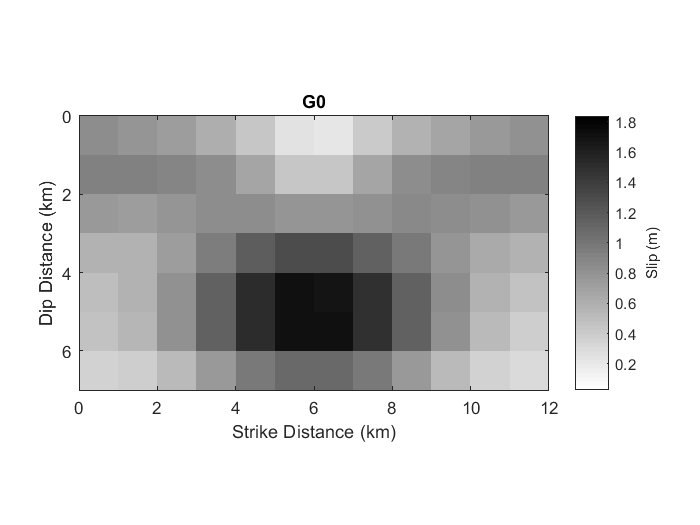

% Απεικόνιση του μοντέλου Variable Slip των συνθετικών μετρήσεων με μικρό σφάλμα
figure()

x = [min(Data_Fault.data(:,4)) max(Data_Fault.data(:,4))];
y = [min(Data_Fault.data(:,5)) max(Data_Fault.data(:,5))];

VarSlip = reshape(Slips_grid(:,1), [SizeY SizeX]);
imagesc(x,y,VarSlip);
colormap(flipud(gray)); axis equal;
caxis([MinGrid MaxGrid])
axis([0 Leng 0 Wid])
xticks(0:2:Leng); yticks(0:2:Wid)
h = colorbar('Ticks',0:0.2:MaxGrid);
ylabel(h,'Slip (m)')

xlabel('Strike Distance (km)'); ylabel('Dip Distance (km)');
title('G0')

Εφαρμόζεται η ανάλυση PCA. Μπορεί να γίνει και αναλυτικά, αλλά εφόσον υπάρχει έτοιμη function στη Matlab θα χρησιμοποιηθεί αυτή. Μεταβλητές (variables) n θεωρούνται τα Slips του κάθε patch ενός μοντέλου, ενώ παρατηρήσεις (observations) m ο αριθμός των συγκρινόμενων μοντέλων. Καθώς στην περίπτωση μας ο αριθμός των μεταβλητών (84 patches) είναι πολύ μεγαλύτερος από των παρατηρήσεων (11 μοντέλα Variable Slip - 1 συνθετικών δεδομένων και 10 Noise), η PCA θα έχει m-1 βαθμούς ελευθερίας. Αυτό σημαίνει πως ο αριθμός των eigenvalues που εξάγεται θα είναι 10.

% Υπολογίζεται ο μέσος όρος slip για κάθε patch ('muG'), και τα eigenvectors...
    % και eigenvalues των τροποποιημένων συνόλων slip κατά φθίνουσα σειρά...
    % (των τιμών eigenvalues)
[evectorsG, scoreG, evaluesG, tG, expG, muG] = pca(Slips_grid');

% Τα τροποποιημένα σύνολα slip μπορούν να δειχθούν εάν αφαιρεθεί από κάθε μοντέλο...
    % Variable Slip το μοντέλο με τους μέσους όρους slip για κάθε patch ('muL').
shifted_Slips_G = Slips_grid - repmat(muG',1,n_models+1);


Μπορούμε και να δείξουμε το μοντέλο μέσων όρων Slips (Gm) σε grayscale:

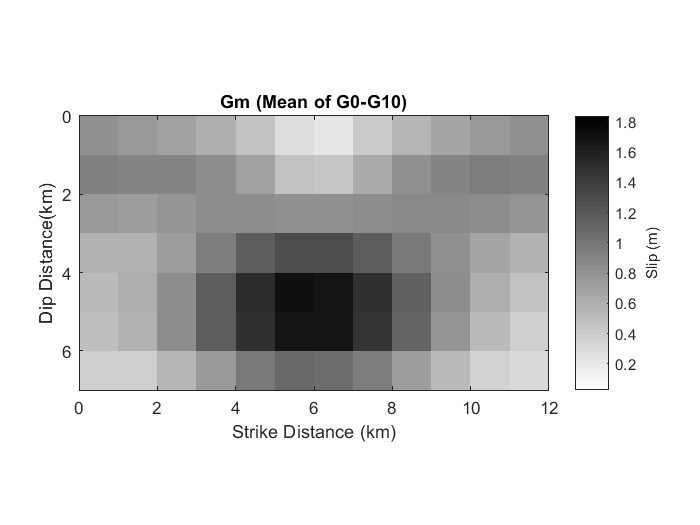

% Απεικόνιση του μοντέλου μέσων Variable Slip ('muG')
figure()

muG_res = reshape(muG', [SizeY SizeX]);
imagesc(x,y,muG_res);
colormap(flipud(gray)); axis equal;
caxis([MinGrid MaxGrid])
xticks(0:2:Leng); yticks(0:2:Wid)
axis([0 Leng 0 Wid])
h = colorbar('Ticks',0:0.2:MaxGrid);
ylabel(h,'Slip (m)')

xlabel('Strike Distance (km)'); ylabel('Dip Distance(km)');
title('Gm (Mean of G0-G10)')

H expG δηλώνει το ποσοστό της μεταβλητότητας (variance) που εξηγεί η κάθε eigenvalue. Χρησιμοποιείται έτσι για την επιλογή του αριθμού των Principal Components, ανάλογα το ποσοστό της μεταβλητότητας που επιθυμούμε να συμπεριλάβουμε. Απεικονίζουμε τη σχέση αυτή σε ένα γράφημα Pareto.

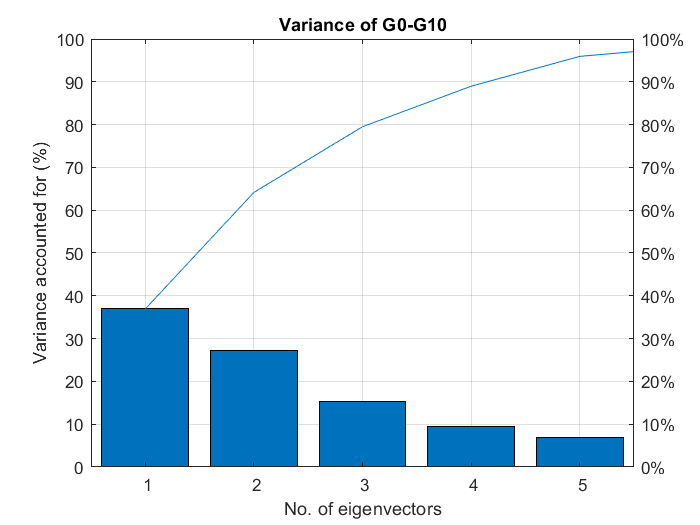

figure()
pareto(expG)
xlabel('No. of eigenvectors')
ylabel('Variance accounted for (%)')
grid on
title('Variance of G0-G10')

Ορίζεται ο αριθμός των Principal Components που θα χρησιμοποιήσουμε για την επιθυμητή μεταβλητότητα.

% Διατήρηση μόνο των κύριων eigenvectors (principal components)
num_eigenvG = find(cumsum(expG)>varianceG,1);
evectorsG_pc = evectorsG(:, 1:num_eigenvG);

% Προβολή των τροποποιημένων συνόλων slip στο eigenspace με χρήση των επιλεγμένων ...
    % eigenvectors (γίνεται και αυτόματα, εκτελέστε μόνο για εναλλακτικό ...
    % Reconstruct των μοντέλων
featuresG = evectorsG_pc' * shifted_Slips_G;

Στο σημείο αυτό μπορούμε να δείξουμε το κάθε eigenvector από αυτά που επιλέξαμε. Προσοχή, δεν αναφερόμαστε ακόμα σε ανακατασκευασμένα μοντέλα Variable Slip, απλά δείχνουμε τα principal components στην επιφάνεια του ρήγματος.

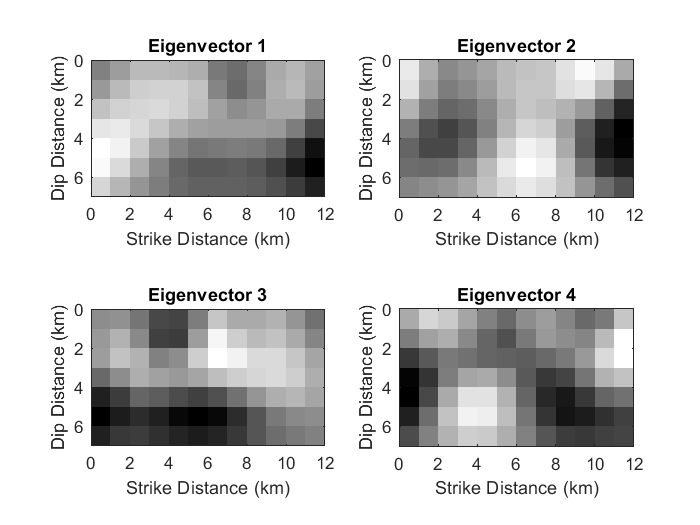

% Απεικόνιση του κάθε eigenvector που επιλέχθηκε, σε φθίνουσα σειρά
figure()
for count = 1:num_eigenvG
    
    subplot(2, ceil(num_eigenvG/2), count);
    evectorG = reshape(evectorsG(:,count), [SizeY SizeX]);
    imagesc(x,y,evectorG);
    colormap(flipud(gray)); axis equal;
    axis([0 Leng 0 Wid])
    xticks(0:2:Leng); yticks(0:2:Wid)
    
    xlabel('Strike Distance (km)'); ylabel('Dip Distance (km)');
    title(['Eigenvector ' num2str(count)])
end

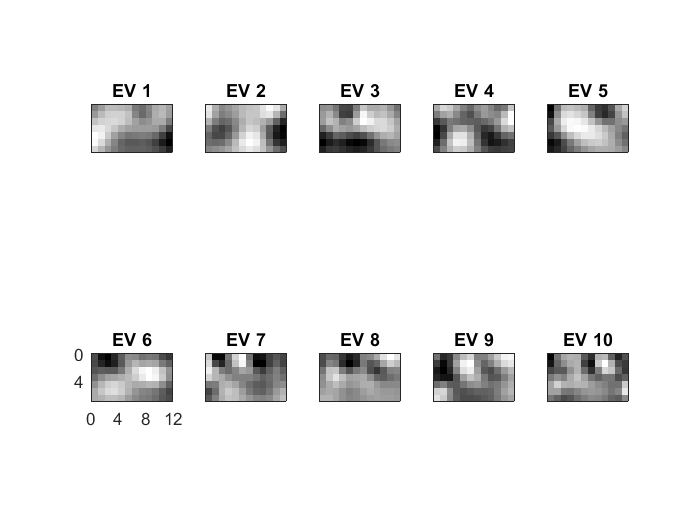

% Απεικόνιση όλων των eigenvector, σε φθίνουσα σειρά
s = size(evaluesG,1);

figure()

for count = 1:s
    
    subplot(2,ceil(s/2), count);
    evectorG = reshape(evectorsG(:,count), [SizeY SizeX]);
    imagesc(x,y,evectorG);
    colormap(flipud(gray)); axis equal;
    axis([0 Leng 0 Wid])
    set(gca,'XTick',[])
    set(gca,'YTick',[])
    title(['EV ' num2str(count)])
       
end

subplot(2,ceil(s/2), s/2+1);
evectorG = reshape(evectorsG(:,s/2+1), [SizeY SizeX]);
imagesc(x,y,evectorG);
colormap(flipud(gray)); axis equal;
axis([0 Leng 0 Wid])
xticks(0:4:Leng); yticks(0:4:Wid)
title(['EV ' num2str(s/2+1)])

Μπορούμε να ανακατασκευάσουμε τα μοντέλα Variable Slip που εισάγαμε στο σύστημα χρησιμοποιώντας πλέον μόνο τον αριθμό των principal components που επιλέξαμε. Τα νέα μοντέλα αποτελούν μια προσέγγιση των αρχικών ρηγμάτων, και υπάρχει ταύτιση όταν χρησιμοποιείται ο πλήρης αριθμός των eigenvectors. Στους τίτλους, το G0 αναφέρεται στο μοντέλο συνθετικών δεδομένων grid, ενώ τα G1, G2, G3 στα μοντέλα Noise Grid 1, 2, 3 κλπ. Τα ανακατασκευασμένα μοντέλα τα ονομάζουμε RG0, RG1 κλπ.

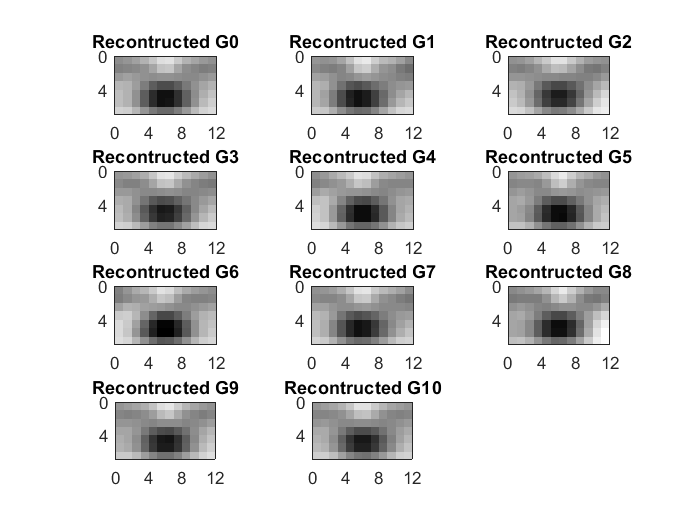

% Reconstruct των μοντέλων Variable Slip με χρήση μόνο των principal components
Approx_SlipsG = (scoreG(:,1:num_eigenvG) * evectorsG(:,1:num_eigenvG)' + ...
    repmat(muG,n_models+1,1))';

Approx_SlipsG_alt = evectorsG_pc*featuresG+repmat(muG',1,n_models+1); ...
    % Εναλλακτικός τρόπος

% Απεικόνιση των reconstructed Variable Slip models
figure()
for count = 1:n_models+1
    subplot(4, ceil((n_models+1)/4), count);
    App_SlipG = reshape(Approx_SlipsG(:,count), [SizeY SizeX]);
    imagesc(x,y,App_SlipG);
    colormap(flipud(gray)); axis equal;
    caxis([MinGrid MaxGrid])
    axis([0 Leng 0 Wid])
    
    xticks(0:4:Leng); yticks(0:4:Wid)
    title(['Recontructed G' num2str(count-1)])
    
end

Δημιουργούμε και αρχείο στο Excel ('PCA Grid Noise.xlsx') με τα αποτελέσματα για πλοτάρισμα στο Origin. Τα sheets PC1, PC2 κλπ. πειρλαμβάνουν τις τιμές για κάθε κύριο Eigenvector (principal component). Τα sheets G0, G1 κλπ. περιέχουν τα μοντέλα Variable Slip (G0: synthetic data (grid), G1: Grid Noise Model 1 etc.). Τα sheets Recontructed G0, Recontructed G1 κλπ. περιέχουν τα Reconstructed μοντέλα Variable Slip χρησιμοποιώντας μόνο τα επιλεγμένα Principal Components. To MeanG περιέχει το μέσο μοντέλο Variable Slip (Gm).

% Δημιουργία αρχείου 'PCA Grid Noise.xlsx' εντός του υποφακέλου 'MS Files'
PC_Table_G = Data_Fault.data(:,[1:7 11 12]);
PCG_size = size(PC_Table_G);

mkdir 'MS Files'\


filename = fullfile(pwd,'MS Files','PCA Grid Noise.xlsx');
delete(filename)

T1 = {'Latitude (deg)','Longitude (deg)','Depth (km)','Strike Distance (km)',...
    'Dip Distance (km)','Patch Lenth (km)','Patch Width (km)',...
    'Strike (deg)','Dip (deg)','Eigenvector (m)'};

    % Principal Components
    for count = 1:num_eigenvG
        PC_Table_G(:,10) = evectorsG(:,count);
        xlswrite(filename,T1,['PC' num2str(count)],'A1:J1')
        xlswrite(filename,PC_Table_G,['PC' num2str(count)], ...
            ['A2:J' num2str(PCG_size(1)+1)])    
    end


T2 = T1; T2(end) = {'Slip (m)'};

    % Αρχικά μοντέλα Variable Slip
    for count = 1:n_models+1
        PC_Table_G(:,10) = Slips_grid(:,count);
        xlswrite(filename,T2,['G' num2str(count-1)],'A1:J1')
        xlswrite(filename,PC_Table_G,['G' num2str(count-1)], ...
            ['A2:J' num2str(PCG_size(1)+1)])
    end


    % Reconstructed μοντέλα Variable Slip
    for count = 1:n_models+1
        PC_Table_G(:,10) = Approx_SlipsG(:,count);
        xlswrite(filename,T2,['Reconstructed G' num2str(count-1)],'A1:J1')
        xlswrite(filename,PC_Table_G,['Reconstructed G' num2str(count-1)], ...
            ['A2:J' num2str(PCG_size(1)+1)])
    end


    % Μέσο μοντέλο Variable Slip
    PC_Table_G(:,10) = muG';
    xlswrite(filename,T2,'MeanG','A1:J1')

    xlswrite(filename,PC_Table_G,'MeanG',['A2:J' num2str(PCG_size(1)+1)])

## Variance - Standard Deviation (RG0-RG10)

Στη συνέχεια θα υπολογίσουμε τη μεταβλητότητα (Variance) και τυπική απόκλιση (Standard Deviation) των Reconstructed μοντέλων RG0-RG10.

% Υπολογισμός των Variance και Standard Deviation
VarSlip_RG = var(Approx_SlipsG,0,2);
SD_Slip_RG = sqrt(VarSlip_RG);

Var_Table_RG = Data_Fault.data(:,[1:7 11 12]);

Var_Table_RG(:,10) = VarSlip_RG;
Var_Table_RG(:,11) = SD_Slip_RG;

VTRG_size = size(Var_Table_RG);

% Εύρεση των Min και Max τιμών των Variance και Standard Deviation στο...
    % σύνολο των μοντέλων RG0-RG10.
MinVar_RG = min(VarSlip_RG);    % Min Variance
MaxVar_RG = max(VarSlip_RG);    % Max Variance
MinSD_RG = min(SD_Slip_RG);     % Min SD
MaxSD_RG = max(SD_Slip_RG);     % Max SD

% Δημιουργία αρχείου 'PCA Slip Variance Grid.xlsx' εντός του υποφακέλου 'MS Files'
T3 = {'Latitude (deg)','Longitude (deg)','Depth (km)','Strike Distance (km)',...
    'Dip Distance (km)','Patch Length (km)','Patch Width (km)',...
    'Strike (deg)','Dip (deg)','Slip Variance (m^2)','Slip SD (m)'};

mkdir 'MS Files'\

filename = fullfile(pwd,'MS Files','PCA Slip Variance Grid.xlsx');
delete(filename)

xlswrite(filename,T3,'Reconstructed Grid Noise','A1:K1')

xlswrite(filename,Var_Table_RG,'Reconstructed Grid Noise',['A2:K' num2str(VTRG_size(1)+1)])

# Rake PCA

Εφαρμόζουμε την ίδια διαδικασία και για τις διευθύνσεις Rake των μοντέλων Variable Slip.

## PCA

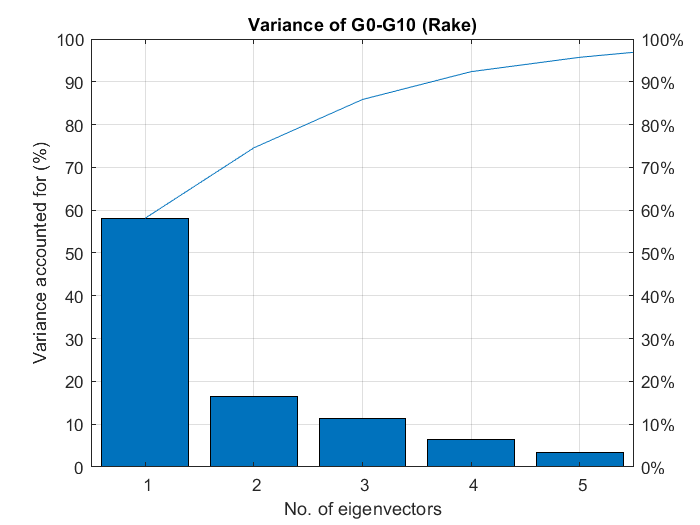

% Υπολογίζεται ο μέσος όρος rake για κάθε patch ('muRakeG'), και τα eigenvectors...
    % και eigenvalues των τροποποιημένων συνόλων slip κατά φθίνουσα σειρά...
    % (των τιμών eigenvalues)
[evectorsRakeG, scoreRakeG, evaluesRakeG, tRakeG, expRakeG, muRakeG] = pca(Rake_grid');

% Διάγραμμα Pareto
figure()
pareto(expRakeG)
xlabel('No. of eigenvectors')
ylabel('Variance accounted for (%)')
grid on
title('Variance of G0-G10 (Rake)')


% Διατήρηση μόνο των κύριων eigenvectors (principal components)
num_eigenvRakeG = find(cumsum(expRakeG)>varianceG,1);
evectorsRakeG_pc = evectorsRakeG(:, 1:num_eigenvRakeG);

% Reconstruct των Rake των μοντέλων Variable Slip με χρήση μόνο των principal components
Approx_RakeG = (scoreRakeG(:,1:num_eigenvRakeG) * evectorsRakeG(:,1:num_eigenvRakeG)' + ...
    repmat(muRakeG,n_models+1,1))';

Δημιουργούμε και αρχείο στο Excel ('PCA Grid Noise Rake.xlsx') με τα αποτελέσματα για πλοτάρισμα στο Origin. Τα sheets PC1, PC2 κλπ. πειρλαμβάνουν τις τιμές για κάθε κύριο Eigenvector (principal component). Τα sheets G0, G1 κλπ. περιέχουν τα Rake των μοντέλων Variable Slip (G0: synthetic data (grid), G1: Grid Noise Model 1 etc.). Τα sheets Recontructed G0, Recontructed G1 κλπ. περιέχουν τα Rake των Reconstructed μοντέλων Variable Slip χρησιμοποιώντας μόνο τα επιλεγμένα Principal Components. To MeanG περιέχει τα Rake του μέσου μοντέλου Variable Slip (Gm).

Τα ανακατασκευασμένα μοντέλα τα ονομάζουμε Rake-RG0, Rake-RG1 κλπ. Αποτελούν διαφορετικές περιπτώσεις από τα μοντέλα RG0-RG10.

% Δημιουργία αρχείου 'PCA Grid Noise Rake.xlsx' εντός του υποφακέλου 'MS Files'
PC_Table_RakeG = Data_Fault.data(:,[1:7 11 12]);
PCG_Rake_size = size(PC_Table_RakeG);

mkdir 'MS Files'\


filename = fullfile(pwd,'MS Files','PCA Grid Noise Rake.xlsx');
delete(filename)

    % Principal Components
    for count = 1:num_eigenvRakeG
        PC_Table_RakeG(:,10) = evectorsRakeG(:,count);
        xlswrite(filename,T1,['PC' num2str(count)],'A1:J1')
        xlswrite(filename,PC_Table_RakeG,['PC' num2str(count)], ...
            ['A2:J' num2str(PCG_Rake_size(1)+1)])    
    end


T4 = T1; T4(end) = {'Rake (deg)'};

    % Αρχικά μοντέλα Variable Slip
    for count = 1:n_models+1
        PC_Table_RakeG(:,10) = Rake_grid(:,count);
        xlswrite(filename,T4,['G' num2str(count-1)],'A1:J1')
        xlswrite(filename,PC_Table_RakeG,['G' num2str(count-1)], ...
            ['A2:J' num2str(PCG_Rake_size(1)+1)])
    end


    % Reconstructed μοντέλα Variable Slip
    for count = 1:n_models+1
        PC_Table_RakeG(:,10) = Approx_RakeG(:,count);
        xlswrite(filename,T4,['Rake-Reconstructed G' num2str(count-1)],'A1:J1')
        xlswrite(filename,PC_Table_RakeG,['Rake-Reconstructed G' num2str(count-1)], ...
            ['A2:J' num2str(PCG_Rake_size(1)+1)])
    end


    % Μέσο μοντέλο Variable Slip
    PC_Table_RakeG(:,10) = muRakeG';
    xlswrite(filename,T4,'MeanG','A1:J1')

    xlswrite(filename,PC_Table_RakeG,'MeanG',['A2:J' num2str(PCG_Rake_size(1)+1)])

## Rake Variance - Standard Deviation (Rake-RG0 -- Rake-RG10)

Στη συνέχεια θα υπολογίσουμε τη μεταβλητότητα (Variance) και τυπική απόκλιση (Standard Deviation) των Rake των Reconstructed μοντέλων Rake-RG0 -- Rake-RG10.

% Υπολογισμός των Variance και Standard Deviation
VarRake_RG = var(Approx_RakeG,0,2);
SD_Rake_RG = sqrt(VarRake_RG);

Var_Table_Rake_RG = Data_Fault.data(:,[1:7 11 12]);

Var_Table_Rake_RG(:,10) = VarRake_RG;
Var_Table_Rake_RG(:,11) = SD_Rake_RG;

VTRG_Rake_size = size(Var_Table_Rake_RG);

% Εύρεση των Min και Max τιμών των Variance και Standard Deviation στο...
    % σύνολο των μοντέλων Rake-RG0 -- Rake-RG10.
MinVar_R_RG = min(VarRake_RG);    % Min Variance
MaxVar_R_RG = max(VarRake_RG);    % Max Variance
MinSD_R_RG = min(SD_Rake_RG);     % Min SD
MaxSD_R_RG = max(SD_Rake_RG);     % Max SD

% Δημιουργία αρχείου 'PCA Rake Variance Grid.xlsx' εντός του υποφακέλου 'MS Files'
T5 = {'Latitude (deg)','Longitude (deg)','Depth (km)','Strike Distance (km)',...
    'Dip Distance (km)','Patch Length (km)','Patch Width (km)',...
    'Strike (deg)','Dip (deg)','Rake Variance (deg^2)','Rake SD (deg)'};

mkdir 'MS Files'\

filename = fullfile(pwd,'MS Files','PCA Rake Variance Grid.xlsx');
delete(filename)

xlswrite(filename,T5,'Reconstructed Grid Noise','A1:K1')

xlswrite(filename,Var_Table_Rake_RG,'Reconstructed Grid Noise',['A2:K' num2str(VTRG_Rake_size(1)+1)])

% Αποθήκευση του Workspace
save PCA_grid.mat